# ECE 301 Ch 4 Windowed Signal Example

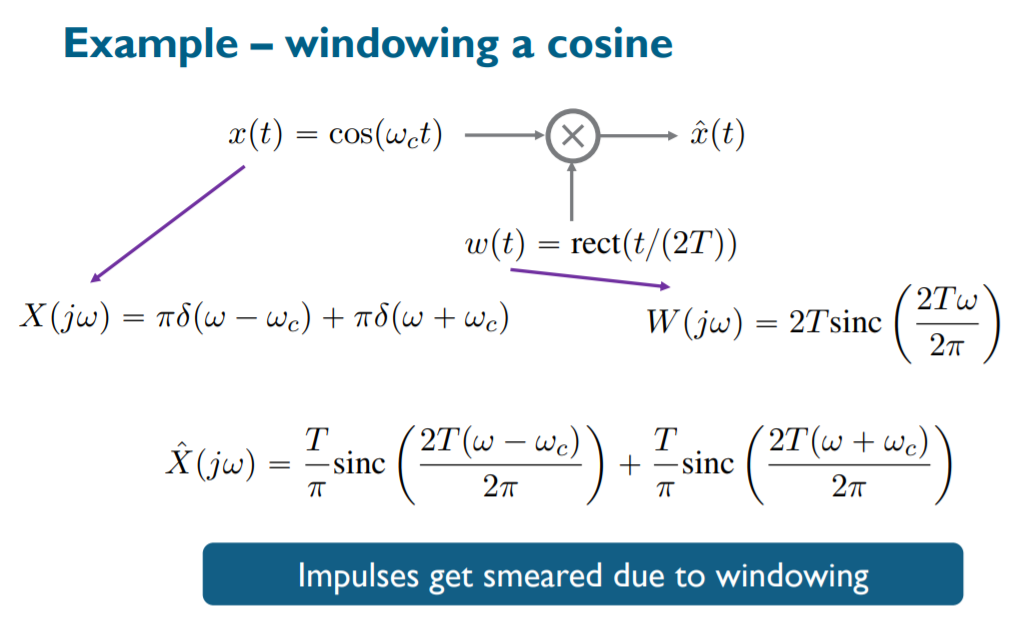

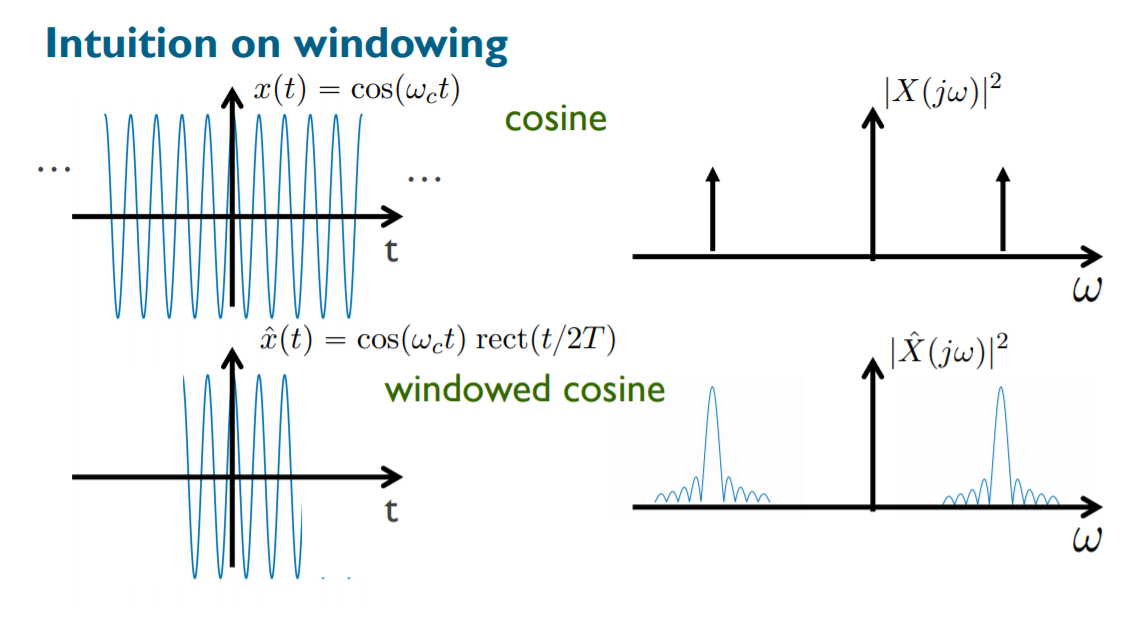

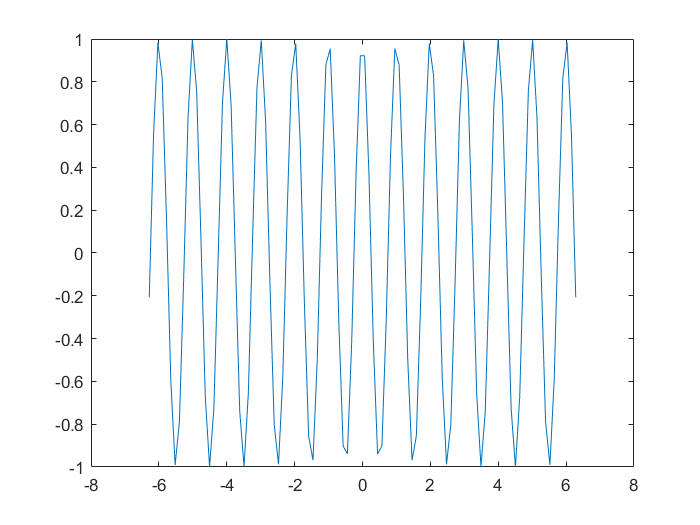

clear; close all;
f = 1;
t= linspace(-2*pi,2*pi);
x=cos(2*pi*t);
plot(t,x)

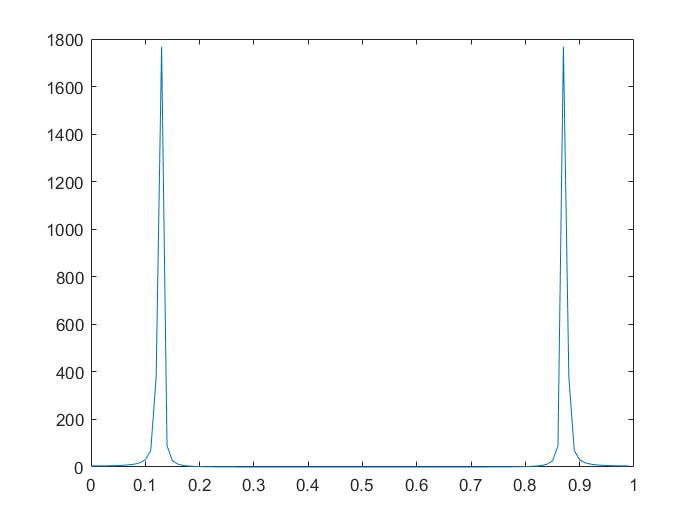

X=fft(x);
f_X = (0:length(X)-1)*f/length(X);
X_sqd=abs(X).^2;
plot(f_X, X_sqd)

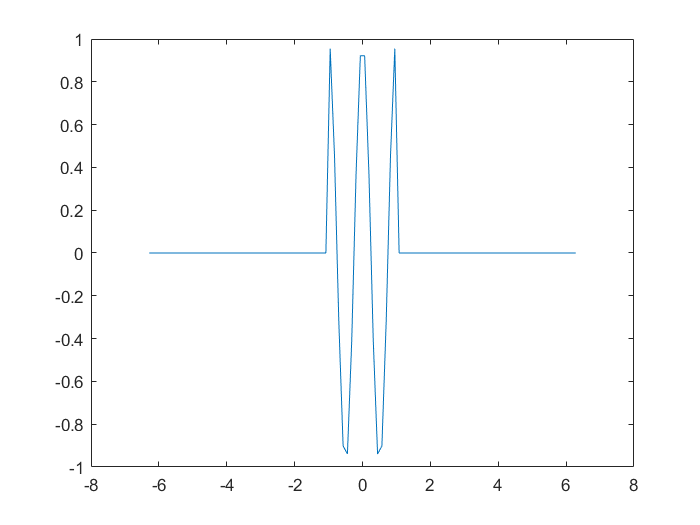

x_hat=x.*rectangularPulse(t/2);
plot(t,x_hat)

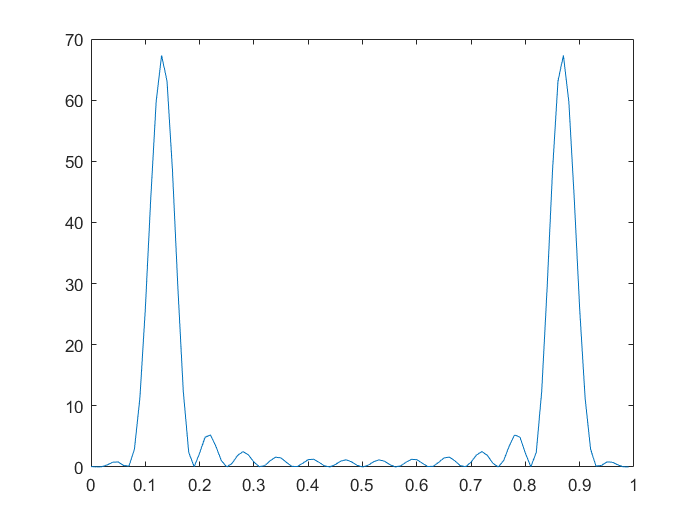

X_hat=fft(x_hat);
f_Y = (0:length(X_hat)-1)*f/length(X_hat);
X_hat_sqd=abs(X_hat).^2;
plot(f_Y, X_hat_sqd)